# RVC2: Chapter 8 - Velocity Relationships

close all
bdclose('all')
clear
clc

## 8.1  Manipulator Jacobian

mdl_planar2_sym
p2

p2 = 
two link:: 2 axis, RR, stdDH, fastRNE, Symbolic                  
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|         a1|          0|          0|
|  2|         q2|          0|         a2|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+



syms q1 q2 real

TE = p2.fkine( [q1 q2] );

p = TE.t; p = p(1:2)

$$p = \left(\begin{array}{c} a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right)\\ a_{2}\,\sin\left(q_{1}+q_{2}\right)+a_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$


J = jacobian(p, [q1 q2]);
simplify(J)

$$ans = \left(\begin{array}{cc} -a_{2}\,\sin\left(q_{1}+q_{2}\right)-a_{1}\,\sin\left(q_{1}\right) & -a_{2}\,\sin\left(q_{1}+q_{2}\right)\\ a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right) & a_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$



mdl_puma560
J = p560.jacob0(qn)

J =     0.1501    0.0144    0.3197         0         0         0
    0.5963    0.0000    0.0000         0         0         0
    0.0000    0.5963    0.2910         0         0         0
   -0.0000         0         0    0.7071         0    1.0000
   -0.0000   -1.0000   -1.0000   -0.0000   -1.0000   -0.0000
    1.0000    0.0000    0.0000   -0.7071    0.0000   -0.0000


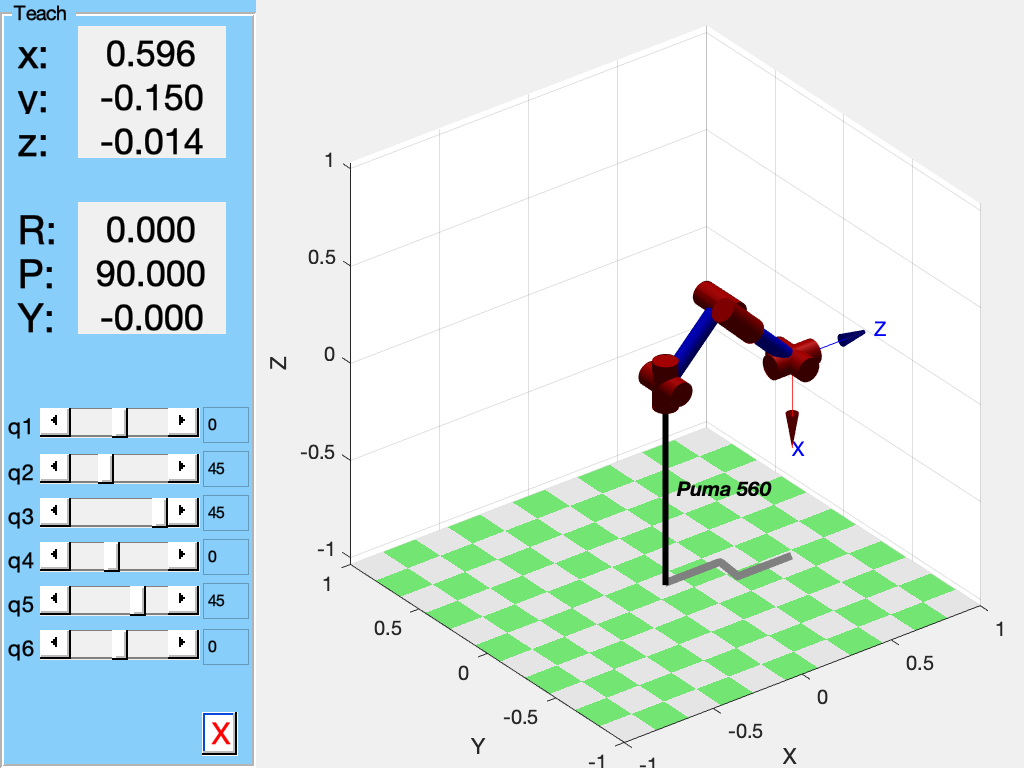


p560.teach(qn)

## 8.1.1  Jacobian in end-effector coordinate frame

p560.jacobe(qn)

ans =    -0.0000   -0.5963   -0.2910         0         0         0
    0.5963    0.0000    0.0000         0         0         0
    0.1500    0.0144    0.3197         0         0         0
   -1.0000         0         0    0.7071         0         0
   -0.0000   -1.0000   -1.0000   -0.0000   -1.0000         0
   -0.0000    0.0000    0.0000    0.7071    0.0000    1.0000


## 8.1.2  Analytical Jacobian

rpy2jac(0.1, 0.2, 0.3)

ans =     0.9363   -0.2955         0
    0.2896    0.9553         0
   -0.1987         0    1.0000



p560.jacob0(qn, 'eul')

ans =     0.1501    0.0144    0.3197         0         0         0
    0.5963    0.0000    0.0000         0         0         0
    0.0000    0.5963    0.2910         0         0         0
    1.0000    0.0000    0.0000   -0.7071    0.0000    0.0000
   -0.0000   -1.0000   -1.0000   -0.0000   -1.0000         0
   -0.0000    0.0000    0.0000    0.7071    0.0000    1.0000


## 8.2 Jacobian condition and manipulability

## 8.2.1  Jacobian singularities

J = p560.jacob0(qr)

J =     0.1500   -0.8636   -0.4318         0         0         0
    0.0203    0.0000    0.0000         0         0         0
         0    0.0203    0.0203         0         0         0
         0         0         0         0         0         0
         0   -1.0000   -1.0000         0   -1.0000         0
    1.0000    0.0000    0.0000    1.0000    0.0000    1.0000



det(J)

ans = 0


rank(J)

ans = 5



jsingu(J)

1 linearly dependent joints:
  q6 depends on: q4 



qns = qr; qns(5) = 5*pi/180

qns =          0    1.5708   -1.5708         0    0.0873         0



J=p560.jacob0(qns);

qd = inv(J)*[0 0 0.1 0 0 0]' ;
qd'

ans =    -0.0000   -4.9261    9.8522    0.0000   -4.9261         0



det(J)

ans = -1.5509e-05


cond(J)

ans = 235.2498

qd = inv(J)*[0 0 0 0 0.2 0]';
qd'

ans =     0.0000    0.0000    0.0000    0.0000   -0.2000    0.0000


## 8.2.2  Manipulability

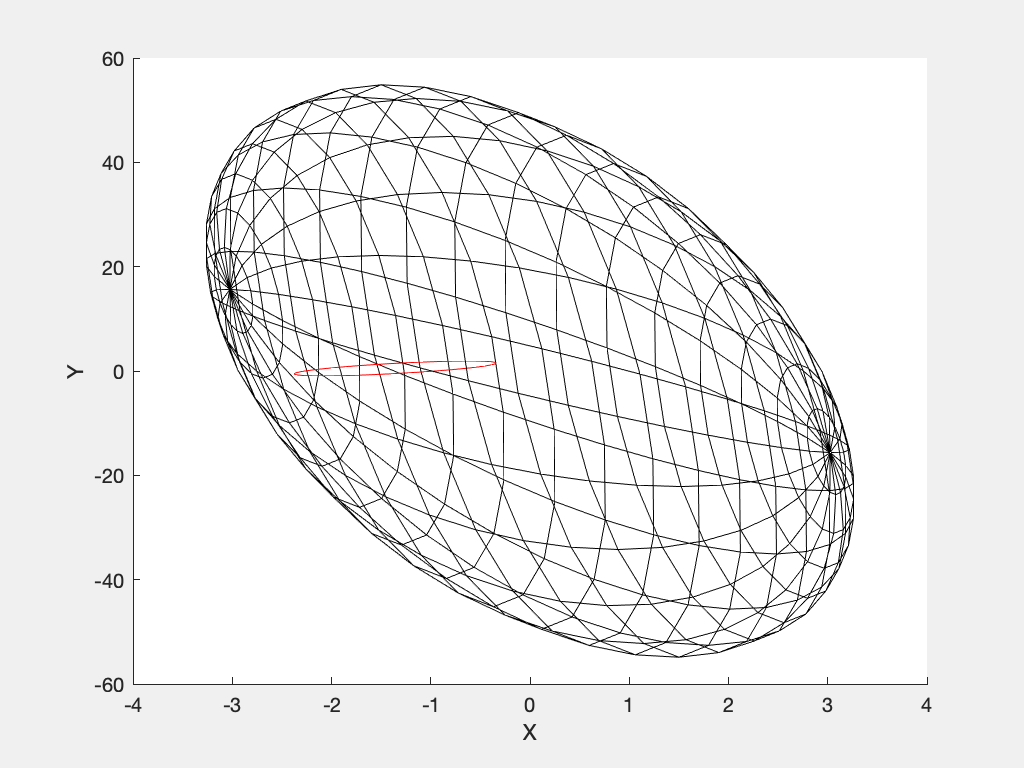

clf

mdl_planar2

p2.vellipse([30 40], 'deg')

%BUG p2.teach([0 0], 'callback', @vellipse, 'view', 'top')

J = p560.jacob0(qns);
J = J(1:3, 1:3);

plot_ellipse_inv(J*J'); xyzlabel

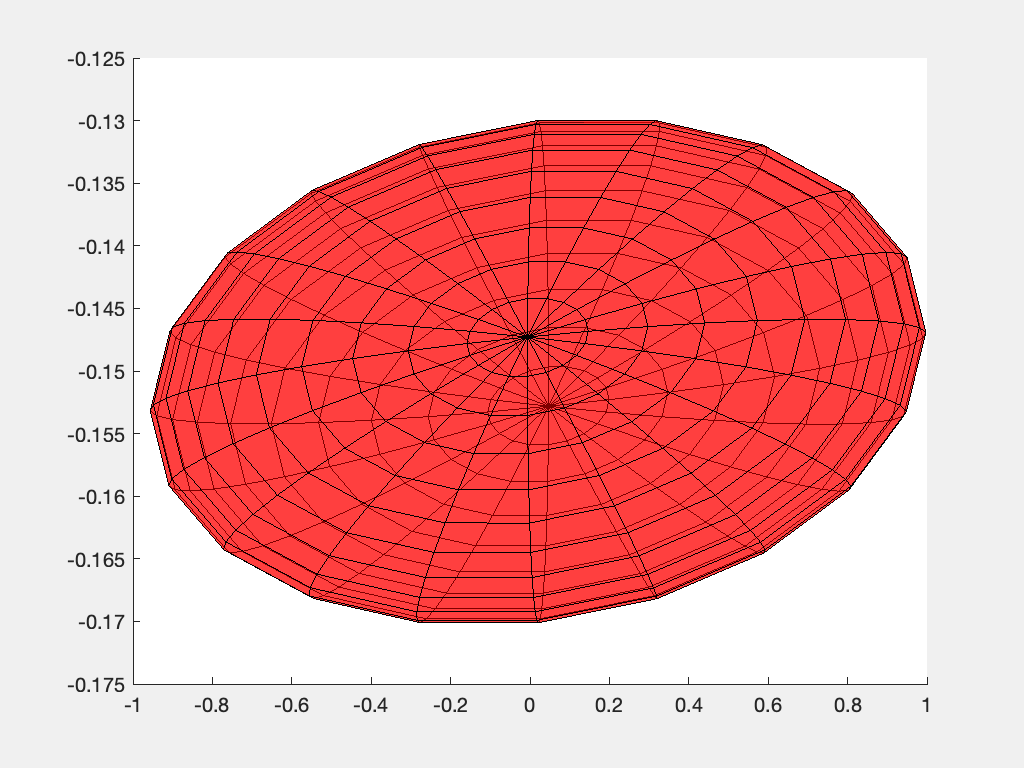

 

clf
p560.vellipse(qns, 'trans');

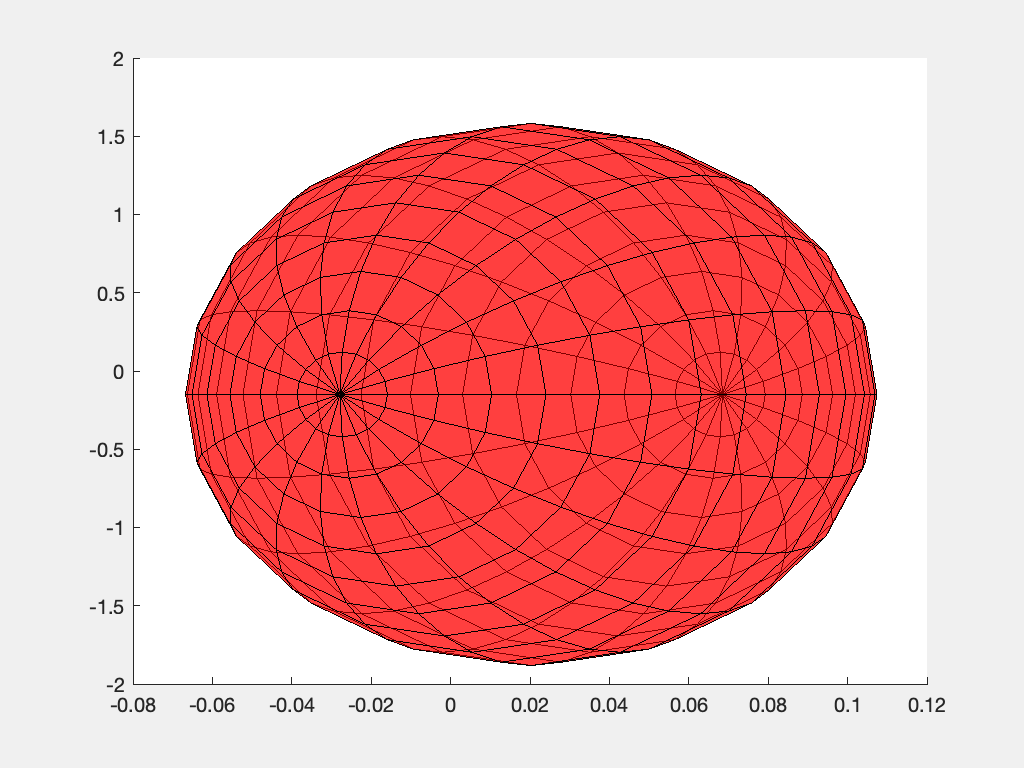


clf
p560.vellipse(qns, 'rot')


m = p560.maniplty(qr)

m = 0


p560.maniplty(qr)

Manipulability: translation 0.00017794, rotation 0



p560.maniplty(qn)

Manipulability: translation 0.111181, rotation 2.44949


## 8.3  Resolved-rate motion control

sl_rrmc

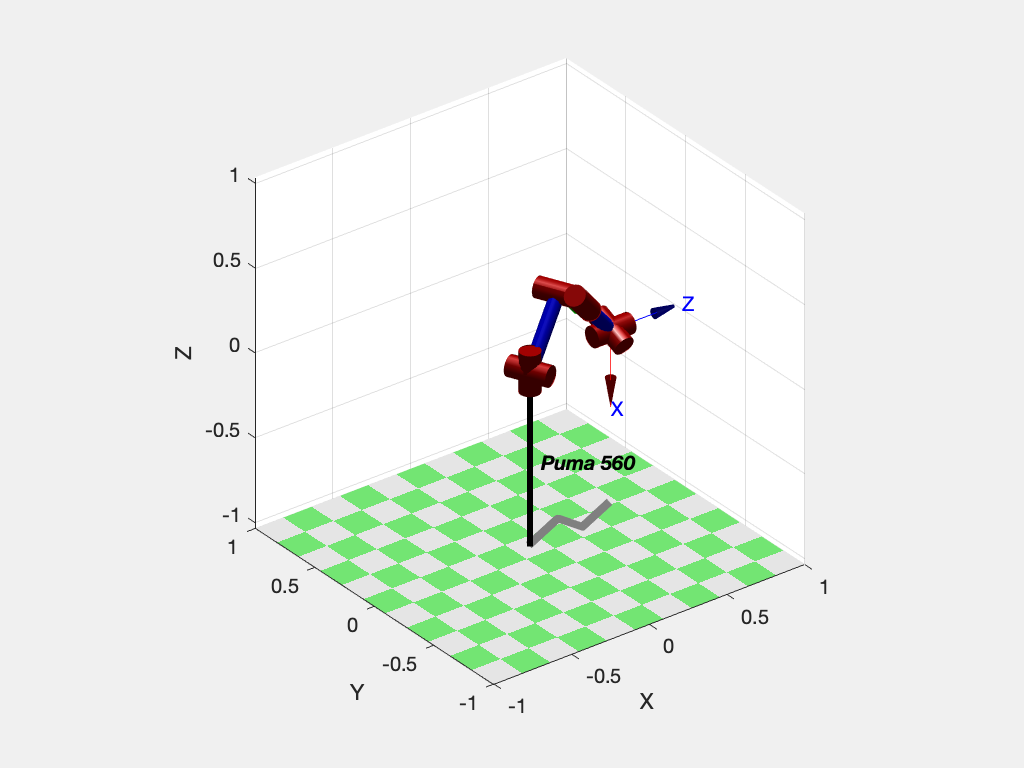


clf
r = sim('sl_rrmc');


t = r.find('tout');
q = r.find('yout');

T = p560.fkine(q);
xyz = transl(T);

mplot(t, xyz(:,1:3))
pause(1)
clf
mplot(t, q(:,1:3))

sl_rrmc2

clf

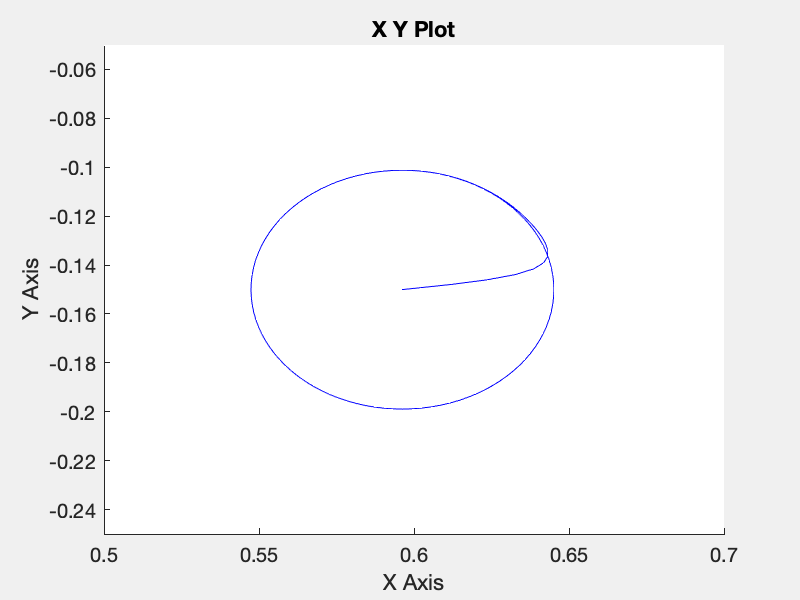

sim('sl_rrmc2');

## 8.4  Under- and over- actuated manipulators

## 8.4.1 Jacobian for under actuated robot

mdl_planar2
qn = [1 1];

J = p2.jacob0(qn)

J =    -1.7508   -0.9093
    0.1242   -0.4161
         0         0
         0         0
         0         0
    1.0000    1.0000



qd = pinv(J) * [0.1 0 0 0 0 0]'

qd =    -0.0698
    0.0431



xd = J*qd;
xd'

ans =     0.0829   -0.0266         0         0         0   -0.0266



Jxy = J(1:2,:);
qd = inv(Jxy)* [0.1 0]'

qd =    -0.0495
   -0.0148



xd = J*qd;
xd'

ans =     0.1000   -0.0000         0         0         0   -0.0642


## 8.4.2  Jacobian for over-actuated robot

mdl_baxter
TE = SE3(0.8, 0.2, -0.2) * SE3.Ry(pi);
q = left.ikine(TE)

q =     0.0895   -0.0464   -0.4259    0.6980   -0.4248    1.0179    0.2998



J = jacob0(left, q);
about(J)

J [double] : 6x7 (336 bytes)



xd = [0.2 0.2 0.2 0 0 0]';
qd = pinv(J) * xd;
qd'

ans =     0.0175    0.5969    0.2321   -1.5889    0.0608    1.1036   -0.1341



rank(J)

ans = 6


N = null(J)

N =    -0.2244
   -0.1306
    0.6018
    0.0371
   -0.7243
    0.0653
    0.2005



norm( J * N(:,1) )

ans = 2.4190e-16


qd_null = [0 0 0 0 1 0 0]';

qp = N * pinv(N) * qd_null;
qp'

ans =     0.1625    0.0946   -0.4359   -0.0269    0.5246   -0.0473   -0.1452



norm( J * qp)

ans = 1.3306e-16

## 8.5 Force relationships

mdl_puma560

## 8.5.1 Transforming wrenches into joint space

tau = p560.jacob0(qn)' * [0 20 0 0 0 0]';
tau'

ans =    11.9261    0.0000    0.0000         0         0         0



tau = p560.jacob0(qn)' * [20 0 0 0 0 0]';
tau'

ans =     3.0010    0.2871    6.3937         0         0         0


## 8.5.2  Force ellipsoids

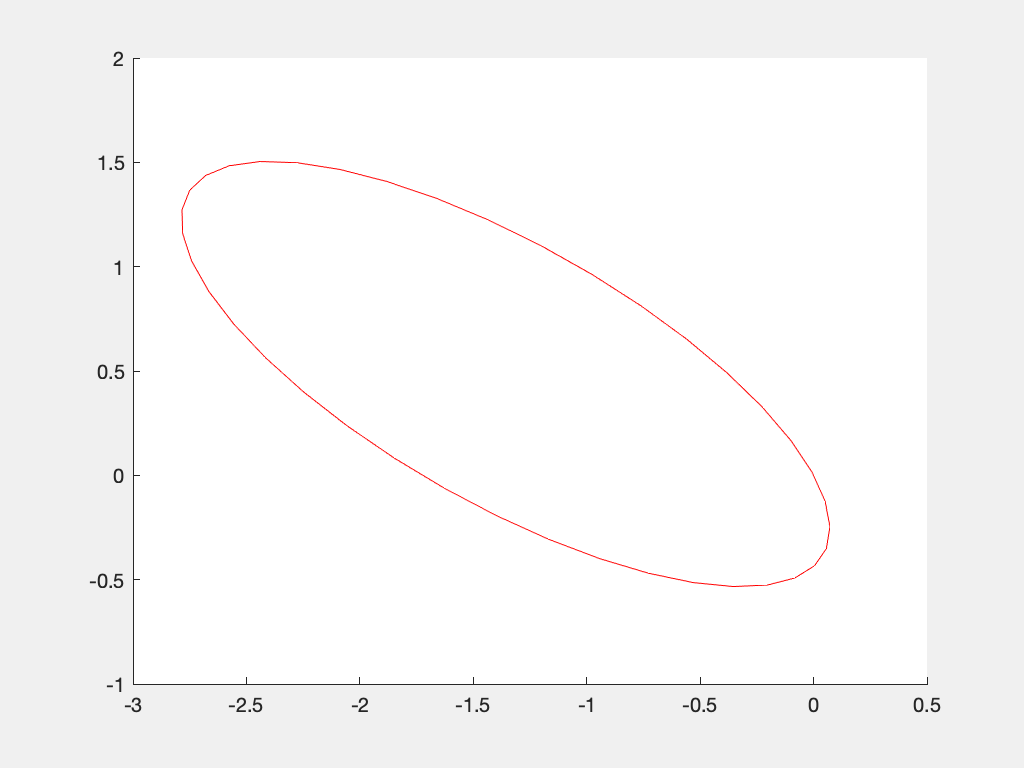

clf
p2.fellipse([30 40], 'deg')


clf

%BUG p2.teach([0 0], 'callback', @(r,q) r.fellipse(q), 'view', 'top')


bdclose('all')